旋转曲面

生成一条***平面曲线***

% x = [-5:.2:5]
% y = x.^2/4 + 4
% plot(x,y)

生成一条三维曲线

生成一条绕z轴的***三维曲面C***

z1 = [-6:.3:6]

z1 =    -6.0000   -5.7000   -5.4000   -5.1000   -4.8000   -4.5000   -4.2000   -3.9000   -3.6000   -3.3000   -3.0000   -2.7000   -2.4000   -2.1000   -1.8000   -1.5000   -1.2000   -0.9000   -0.6000   -0.3000         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000    4.2000    4.5000    4.8000    5.1000    5.4000    5.7000    6.0000


y1 = z1.^2/4 + 4

y1 =    13.0000   12.1225   11.2900   10.5025    9.7600    9.0625    8.4100    7.8025    7.2400    6.7225    6.2500    5.8225    5.4400    5.1025    4.8100    4.5625    4.3600    4.2025    4.0900    4.0225    4.0000    4.0225    4.0900    4.2025    4.3600    4.5625    4.8100    5.1025    5.4400    5.8225    6.2500    6.7225    7.2400    7.8025    8.4100    9.0625    9.7600   10.5025   11.2900   12.1225   13.0000


x1 = z1.^2/4 + 4 - y1

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x1,y1,z1)
hold on
text(0,12,7,'曲线C')


生成一条z轴

z = [-10:.5:20]

z =   -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000


y2 = z - z

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = z - z

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x2,y2,z)
text(0,0,20,'z轴')


生成一条曲线C绕z轴的***旋转曲面***

更具 y = z^2/4  y = sqrt(x^2+y^2） 带入可得 z^2/4 = sqrt(x^2+y^2)

化简得  z = sqrt(4*sqrt(x3.^2+y3.^2)) 或者 z = -sqrt(4*sqrt(x3.^2+y3.^2))

[x3,y3] = meshgrid(-5:.3:5);

surf(x3, y3, real(sqrt(4*sqrt(x3.^2+y3.^2)-16)))
surf(x3, y3, -real(sqrt(4*sqrt(x3.^2+y3.^2)-16)))
%surf(x3, y3, B)

%hold off

***圆锥面***  由直线 z=ay  y = sqrt(x^2+y^2) 可得 z^2 = a^2(x^2+y^2)

% Oyz平面上的直线
[~,y4] = meshgrid(-7:1:7);
z4 = y4

z4 =     -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


x4 = z4-y4

x4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x4,y4,z4,'r')
text(0,8,8,'Oxy平面直线')
% 根据 直线生成 圆锥面
[x5,y5] = meshgrid(-5:.3:5);
z5 = sqrt(x5.^2+y5.^2)

z5 =     7.0711    6.8622    6.6603    6.4661    6.2801    6.1033    5.9363    5.7801    5.6356    5.5036    5.3852    5.2811    5.1923    5.1196    5.0636    5.0249    5.0040    5.0010    5.0160    5.0488    5.0990    5.1662    5.2498    5.3488    5.4626    5.5902    5.7306    5.8830    6.0465    6.2201    6.4031    6.5947    6.7941    7.0007
    6.8622    6.6468    6.4382    6.2370    6.0440    5.8600    5.6859    5.5227    5.3712    5.2326    5.1078    4.9980    4.9041    4.8270    4.7676    4.7265    4.7043    4.7011    4.7170    4.7518    4.8052    4.8765    4.9649    5.0695    5.1894    5.3235    5.4708    5.6303    5.8009    5.9816    6.1717    6.3702    6.5765    6.7897
    6.6603    6.4382    6.2225    6.0141    5.8138    5.6223    5.4406    5.2697    5.1108    4.9649    4.8332    4.7170    4.6174    4.5354    4.4721    4.4283    4.4045    4.4011    4.4181    4.4553    4.5122    4.5880    4.6819    4.7927    4.9193    5.0606    5.2154    5.3824    5.5606    5.7489    5.9464   

surfl(x5,y5,real(z5))
%mesh(x5,y5,-real(z5))


旋转抛物面 由抛物线 z = ay^2 可得   z = a(x^2+y^2)

% 抛物线
[~,y6] = meshgrid(-5:.3:5);
z6 = y6.^2

z6 =    25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000   25.0000
   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900   22.0900
   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   19.3600   

x6 = z6 - y6.^2

x6 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

plot3(x6,y6,z6)

[x7,y7] = meshgrid(-4:.3:4);
z7 = x7.^2 + y7.^2

z7 =    32.0000   29.6900   27.5600   25.6100   23.8400   22.2500   20.8400   19.6100   18.5600   17.6900   17.0000   16.4900   16.1600   16.0100   16.0400   16.2500   16.6400   17.2100   17.9600   18.8900   20.0000   21.2900   22.7600   24.4100   26.2400   28.2500   30.4400
   29.6900   27.3800   25.2500   23.3000   21.5300   19.9400   18.5300   17.3000   16.2500   15.3800   14.6900   14.1800   13.8500   13.7000   13.7300   13.9400   14.3300   14.9000   15.6500   16.5800   17.6900   18.9800   20.4500   22.1000   23.9300   25.9400   28.1300
   27.5600   25.2500   23.1200   21.1700   19.4000   17.8100   16.4000   15.1700   14.1200   13.2500   12.5600   12.0500   11.7200   11.5700   11.6000   11.8100   12.2000   12.7700   13.5200   14.4500   15.5600   16.8500   18.3200   19.9700   21.8000   23.8100   26.0000
   25.6100   23.3000   21.1700   19.2200   17.4500   15.8600   14.4500   13.2200   12.1700   11.3000   10.6100   10.1000    9.7700    9.6200    9.6500    9.8600   10.2500   10.8200  

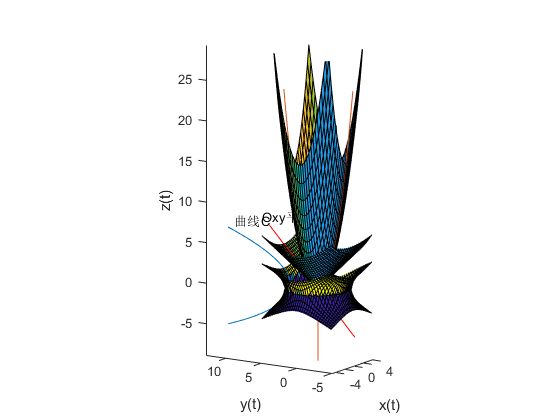

surfl(x7,y7,z7)


xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
axis equal 